# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es): Franck Michael Fierro Chicaiza**

**Fecha: 02/11/2023**

El **objetivo** principal de esta práctica es familiarizarse con los operadores morfológicos.

close all
clear all

1) Lee la Imagen

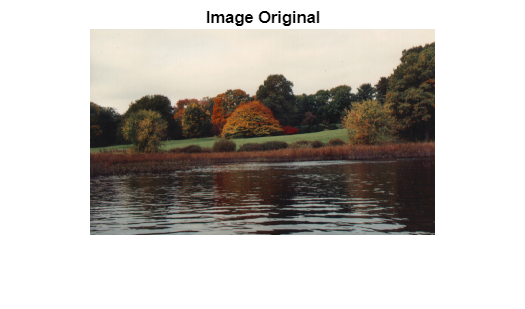

imgOriginal = imread('autumn.tif');

imgBW = imgOriginal;

figure;
imshow(imgOriginal);
title('Image Original');

2) Crea un elemento estructurante. 

se = strel('disk', 5);

3) Realiza operaciones morfológicas en la imagen.

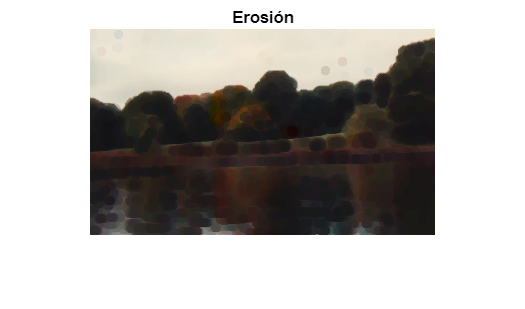

erodeBW = imerode(imgBW,se);
figure;
imshow(erodeBW);
title('Erosión');

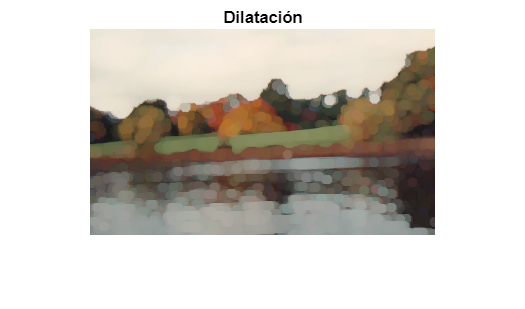

dilateBW = imdilate(imgBW,se);
figure;
imshow(dilateBW);
title('Dilatación');

Se pide: 

- Ejecute el programa cargando la imagen en color `'autumn.tif'`, la imagen en escala de grises `'rice.png' `y  la imagen binaria `'circles.png'`. ¿Qué diferencias ve en el comportamiento de los operadores morfológicos para las distintas imágenes?

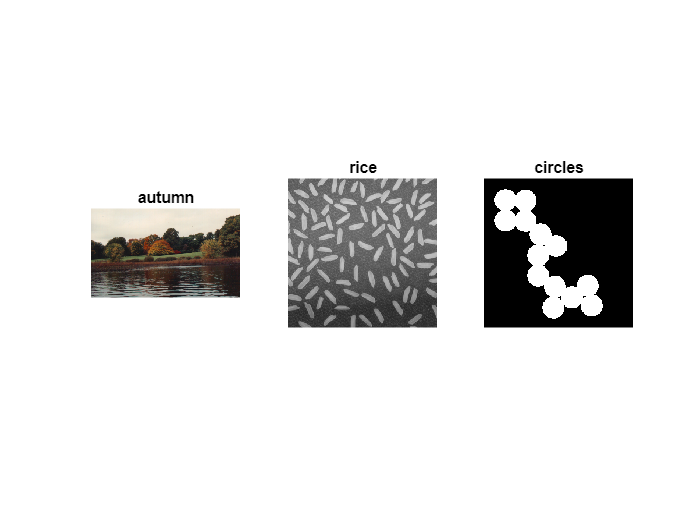

% Cargamos las imagenes
img_autumn = imread('./imagenes/autumn.tif');
img_rice = imread('./imagenes/rice.png');
img_circle = imread('./imagenes/circles.png');

% Definimos el elemento estructurante
se = strel('disk', 5);

% Mostramos las imagenes originales
figure;
suptitle('Imagenes Originales');
subplot(1,3,1), imshow(img_autumn); title('autumn');
subplot(1,3,2), imshow(img_rice); title('rice');
subplot(1,3,3), imshow(img_circle); title('circles');

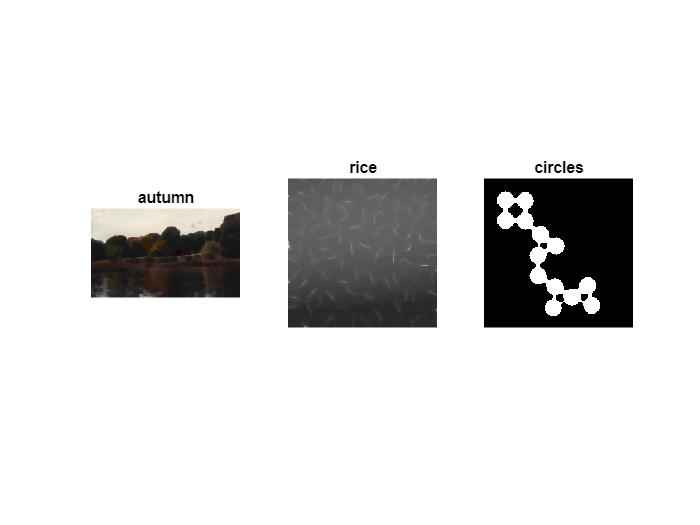

% Erosionamos las imagenes
erode_autumn = imerode(img_autumn, se);
erode_rice = imerode(img_rice, se);
erode_circle = imerode(img_circle, se);

% Mostramos el resultado
figure;
subplot(1,3,1), imshow(erode_autumn); title("autumn");
subplot(1,3,2), imshow(erode_rice); title("rice");
subplot(1,3,3), imshow(erode_circle); title("circles");

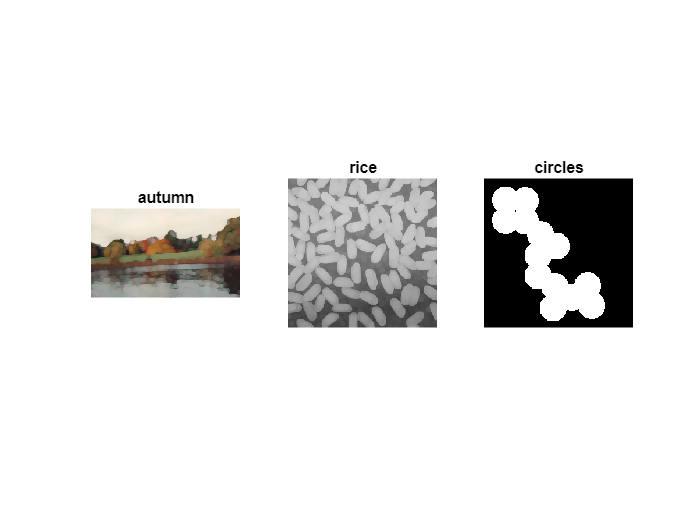

% Dilatamos las imagenes
dilate_autumn = imdilate(img_autumn, se);
dilate_rice = imdilate(img_rice, se);
dilate_circle = imdilate(img_circle, se);

% Mostramos el resultado
figure;
subplot(1,3,1), imshow(dilate_autumn); title("autumn");
subplot(1,3,2), imshow(dilate_rice); title("rice");
subplot(1,3,3), imshow(dilate_circle); title("circles");

Comentarios:

- Elementos estructurales. Observe el efecto de las operaciones morfológicas utilizadas en (3) con diferentes elementos estructurales (ver ayuda: [https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).](https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).)

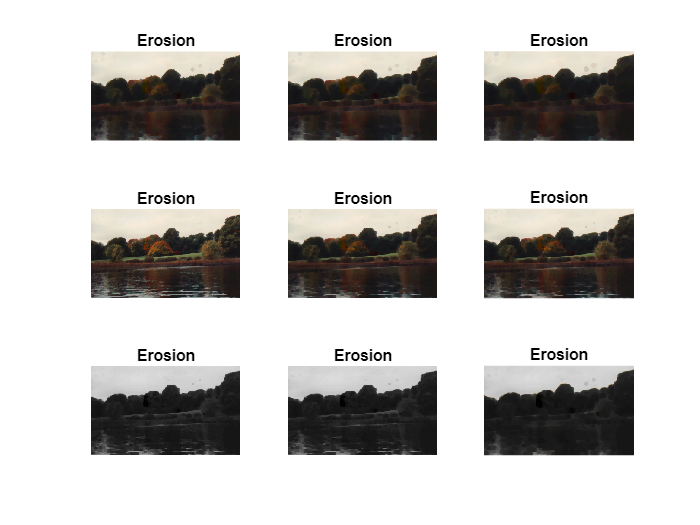


% Elementos estructurantes
estructurantes = {strel("diamond", 5), ...
                    strel("disk", 5, 4), ...
                    strel("octagon", 6), ...
                    strel("line", 5, 45), ...
                    strel("rectangle", [5 6]), ...
                    strel("square", 5), ...
                    strel("cube", 5), ...
                    strel("cuboid", [5 6 5]), ...
                    strel("sphere", 5)};

% Erosion
figure;
for i = 1:length(estructurantes)
    img_erode = imerode(img_autumn, estructurantes{i});
    subplot(3,3,i), imshow(img_erode); title("Erosion");
end

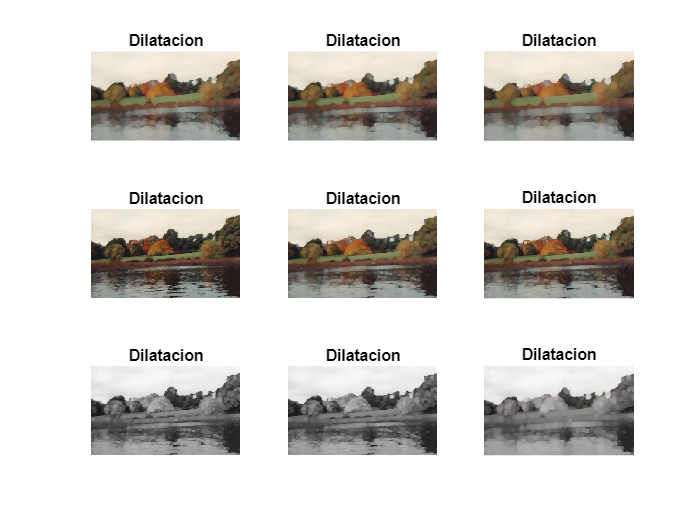


% Dilatacion
figure;
for i = 1:length(estructurantes)
    img_erode = imdilate(img_autumn, estructurantes{i});
    subplot(3,3,i), imshow(img_erode); title("Dilatacion");
end

Comentarios:

- Operadores morfológicos. Cargue la imagen en escala de grises `'rice.png' `y realice una operación de umbralizado con la función `imbinarize`, que por defecto utiliza el método de Otsu. Utilice las funciones `imclose` o `imopen` para eliminar los pequeños píxeles aislados que puedan estar en el fondo de la imagen. Tenga en cuenta que el tipo y tamaño del elemento estructural debe ser ajustado.

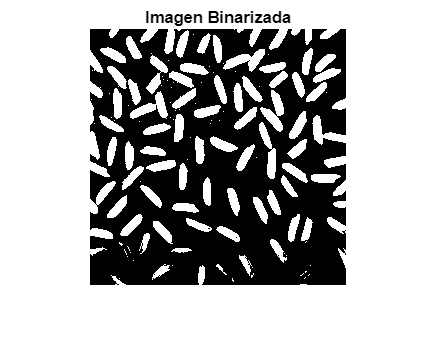

% Conversion de la imagen
bin_rice = imbinarize(img_rice);
figure, imshow(bin_rice); title('Imagen Binarizada');

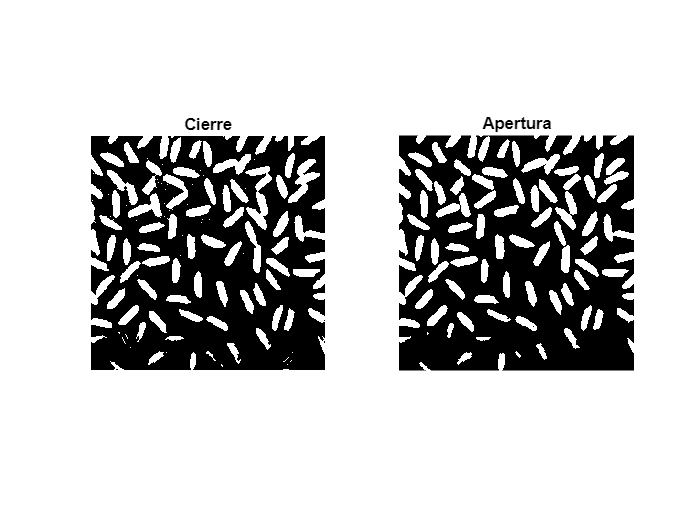

% Elemento estructurante
se = strel('disk', 1);

% Aplicamos imclose y imopen
img_cierre = imclose(bin_rice, se);
img_apertura = imopen(bin_rice, se);

% Mostramos el resultado
figure;
subplot(1,2,1), imshow(img_cierre); title('Cierre');
subplot(1,2,2), imshow(img_apertura); title('Apertura');

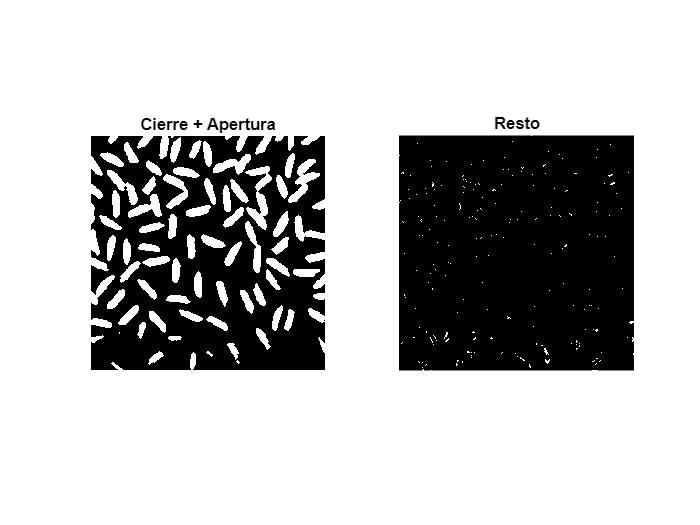

% Aplicando ambas operaciones
img_ca = imopen(img_cierre, se);
img_resto = img_cierre - img_apertura;
% Mostramos el resultado
figure, 
subplot(1,2,1), imshow(img_ca); title('Cierre + Apertura');
subplot(1,2,2), imshow(img_resto); title('Resto');

Comentarios:

- Repita la pregunta anterior pero utilizando la imagen original complementada (utilice la función `imcomplement`).

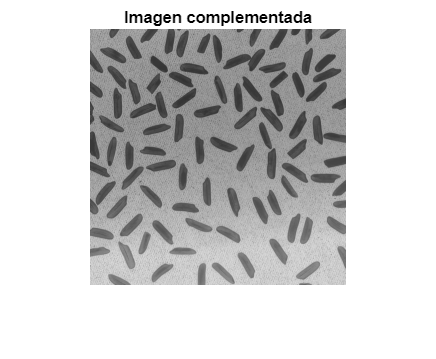

% Complementamos la imagen
com_rice = imcomplement(img_rice);

figure, imshow(com_rice); title('Imagen complementada')

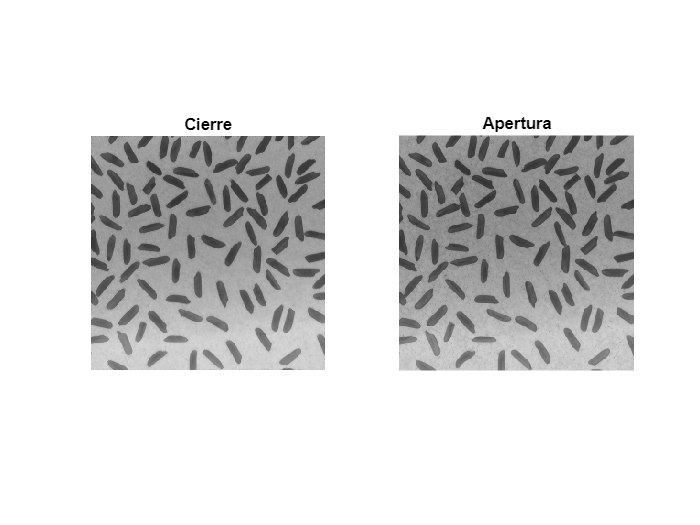

% Elemento estructurante
se = strel('disk', 1);

% Aplicamos imclose y imopen
img_cierre = imclose(com_rice, se);
img_apertura = imopen(com_rice, se);

% Mostramos el resultado
figure,
subplot(1,2,1), imshow(img_cierre); title('Cierre');
subplot(1,2,2), imshow(img_apertura); title('Apertura');

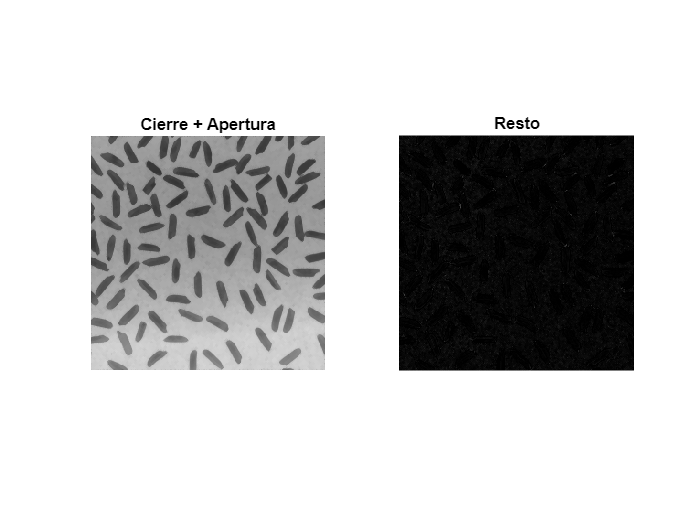

% Aplicando ambas operaciones
img_ca = imopen(img_cierre, se);
img_resto = img_cierre - img_apertura;
% Mostramos el resultado
figure, 
subplot(1,2,1), imshow(img_ca); title('Cierre + Apertura');
subplot(1,2,2), imshow(img_resto); title('Resto');

Comentarios:

% close all
% clear all

Step 1) Reading the Image

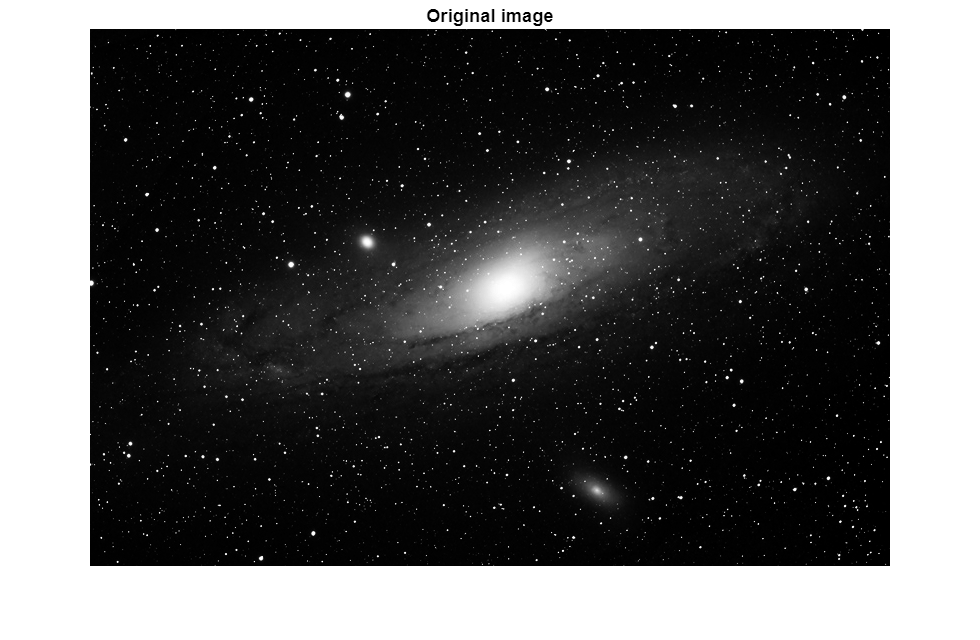

original = imread('./imagenes/galaxy.png');
figure;
imshow(original);
title('Original image');

Step 2) Creating a structuring element.

se = strel('disk',50);

Step 3) Top or Bottom Hat.

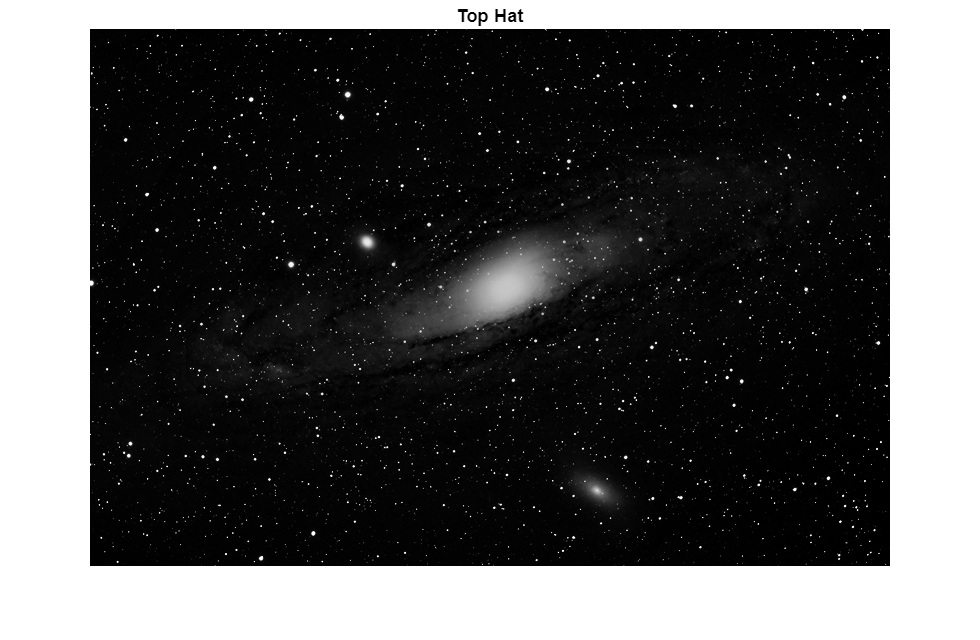

tophat = imtophat(original,se);
figure;
imshow(tophat);
title('Top Hat');

Se pide: 

- Supongamos que sólo nos interesan las pequeñas manchas en la imagen y queremos eliminar la galaxia. La operación (white) top-hat puede eliminar objetos brillantes más grandes y retener pequeñas manchas seleccionando correctamente el tamaño del elemento estructurante. Elija un elemento estructurante en forma de disco (2) y encuentre el radio que le permita mantener las estrellas pequeñas, un radio alrededor de 2 a 6 píxeles, y eliminar la galaxia, más de 50 píxeles. 

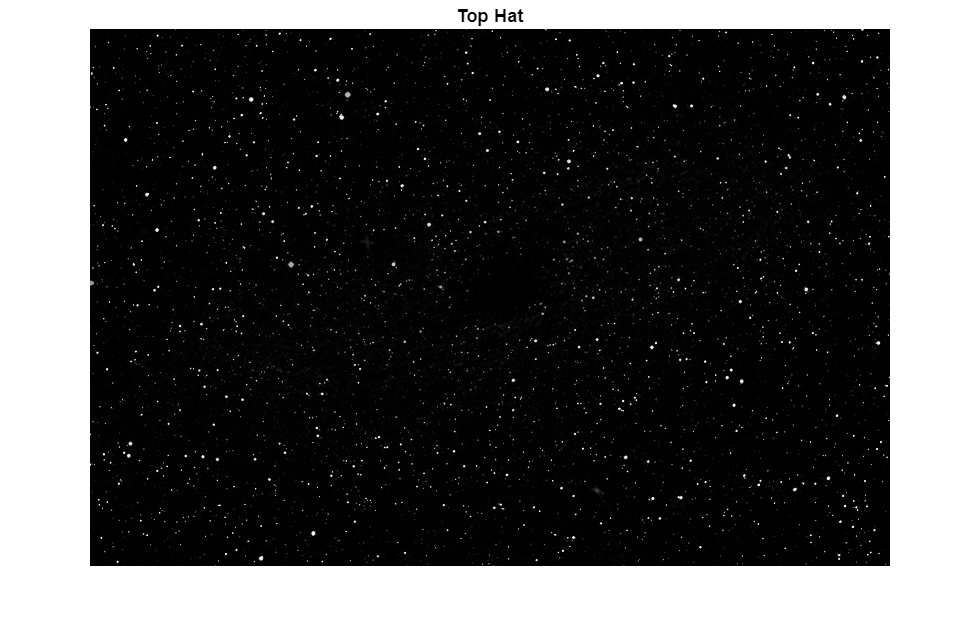

% Elemento estructurante
se = strel('disk', 3);

% Top-hat
tophat = imtophat(original,se);

% Mostramos el resultado
figure;
imshow(tophat);
title('Top Hat');

Comentarios:

- Cuando el fondo es blanco y el primer plano es oscuro, debemos cambiar el enfoque. Obtenga la imagen complementada con la función `imcomplement` (1) y compruebe que La operación (white) top-hat no funciona correctamente. Explique por qué y obtenga una solución.

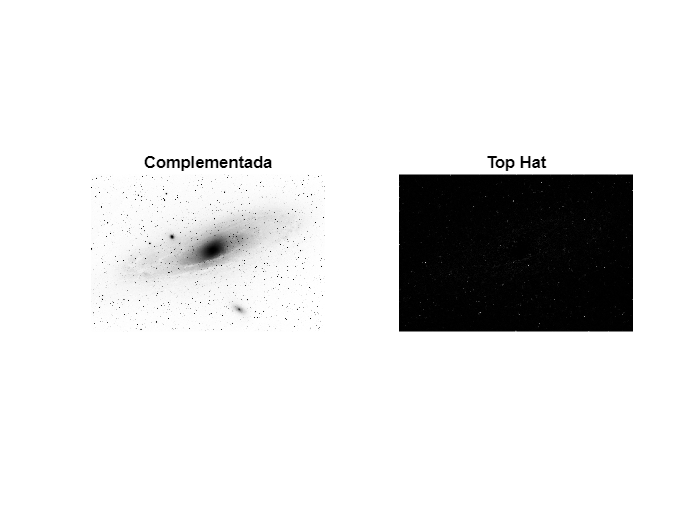

% Obtenemos la imagen complementada
complementada = imcomplement(original);

% Elemento estructurante
se = strel('disk', 3);

% Top-hat
tophat = imtophat(complementada,se);

% Mostramos el resultado
figure;
subplot(1,2,1), imshow(complementada); title('Complementada');
subplot(1,2,2), imshow(tophat); title('Top Hat')

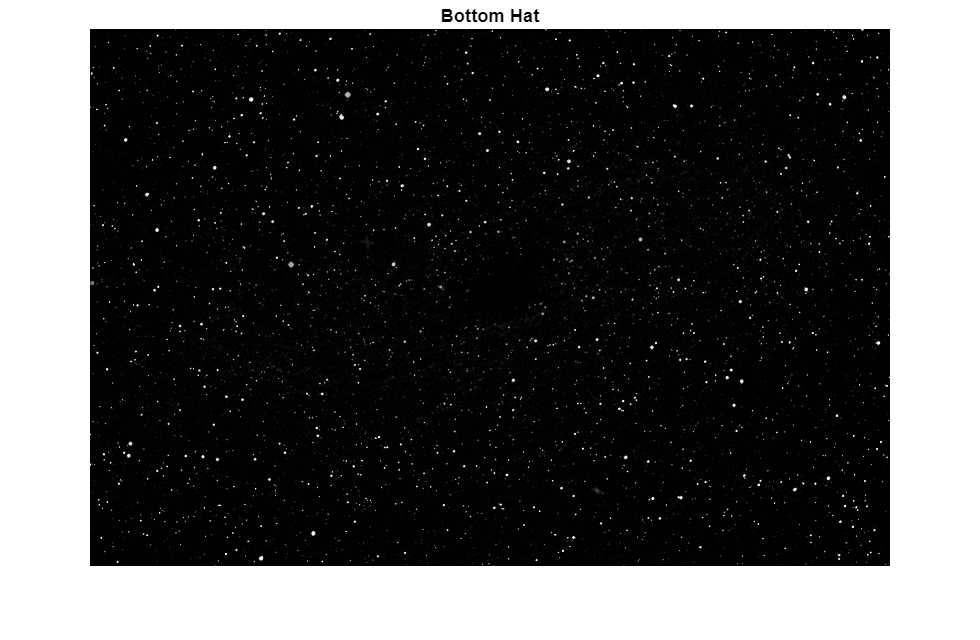

% Solucion: Usar Bottom Hat
% Bottom-hat
bottomhat = imbothat(complementada,se);

% Mostramos el resultado
figure; imshow(bottomhat); title('Bottom Hat');

Comentario: